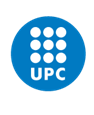

**ESTRUCTURES AEROESPACIALS**

# **The Staircase Project**

*March 2025*

**Julen Aguilera, Sergio Sanz**

**[Note: The assignment can be done in groups of two people.]**

## **Introduction**

In the Netflix adaptation of *The Three-Body Problem* book series, the protagonists attempt to send a preserved human brain into space to intercept an incoming alien fleet. Their goal is to accelerate the probe containing the brain to approximately 1% lightspeed ($c=3\times 10^8$ m/s) in order to reach the fleet within a reasonable timeframe. The idea behind the *Staircase Project* is to propel the probe using a series of nuclear explosions to transfer the momentum of the plasma ejected to a solar sail. In this assignment, we will study the feasibility of this project from a structural point of view.

### Estimation of the thrust force

To make an estimation of the thrust force we will make the following assumptions:

- Each detonation ejects $m_p=4.468\times10^6$ kg of plasma (more or less equivalent to a 10-megaton explosion).

- The plasma is released within $t_p=0.1$ seconds in all directions as a sinusoidal pulse (half-period) advancing at a speed of $V_p=125000$ km/s (see Figure 1).

- The plasma pulse reaches the probe at a distance $d=200$ km.

- The total mass of the probe and solar sail is $M=100$ kg, and the pusher plate surface is $S=900$ m${}^2$.

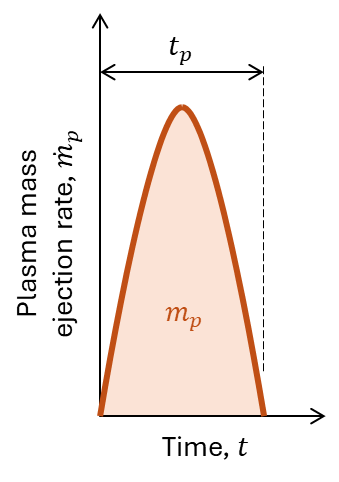

**Figure 1.** Plasma mass ejection rate

Based on these hypothesis, the mass ejection rate of each nuclear explosion is given by:

 $\dot{m}_p(t)= \frac{\pi}{2} \frac{m_p}{t_p} \sin{\frac{\pi t}{t_p}}$, for $0 \leq t \leq t_p$

Considering $S \ll d^2$ and $V \ll V_p$, from the conservation of linear momentum:


$$M \frac{dV}{dt} \approx \dot{m}_p(t) \frac{S}{4 \pi d^2} V_p
$$


Integrating both sides over a period $t_p$ we can obtain the impulse obtained from each nuclear detonation:

$\Delta V \approx \frac{m_p}{M} \frac{S}{4\pi d^2} V_p = 10$ km/s

Acording to these calculations, with 300 concatenated explosions (the number given in the fiction), the probe would reach a velocity close to $V=3000 $ km/s. However, if the detonations are produced at enough distance from one another, the thrust transfered to the structure in each one will be the same. Assuming the force is distributed uniformly over the pusher plate surface, the pressure is given by: 


$$p_\text{T}(t) = \frac{\dot{m}_p(t)}{4 \pi d^2} V_p$$


### Solar sail design

Figure 2 shows a schematic representation of the solar sail. The total mass of the solar sail is $M = $ 100 kg, which includes the mass of the structure (bar elements), $M_\text{S}$. The remaining mass, $M_\text{R} = M - M_\text{S}$, which accounts for the payload, the communications antenna, etc., is distributed: 20% to node 1, 40% to nodes 2, 3, 4 and 5 (10% each), and 40% to node 6.  Reference material properties for each structural component are given in Table 2.

**Table 1.** Material properties.

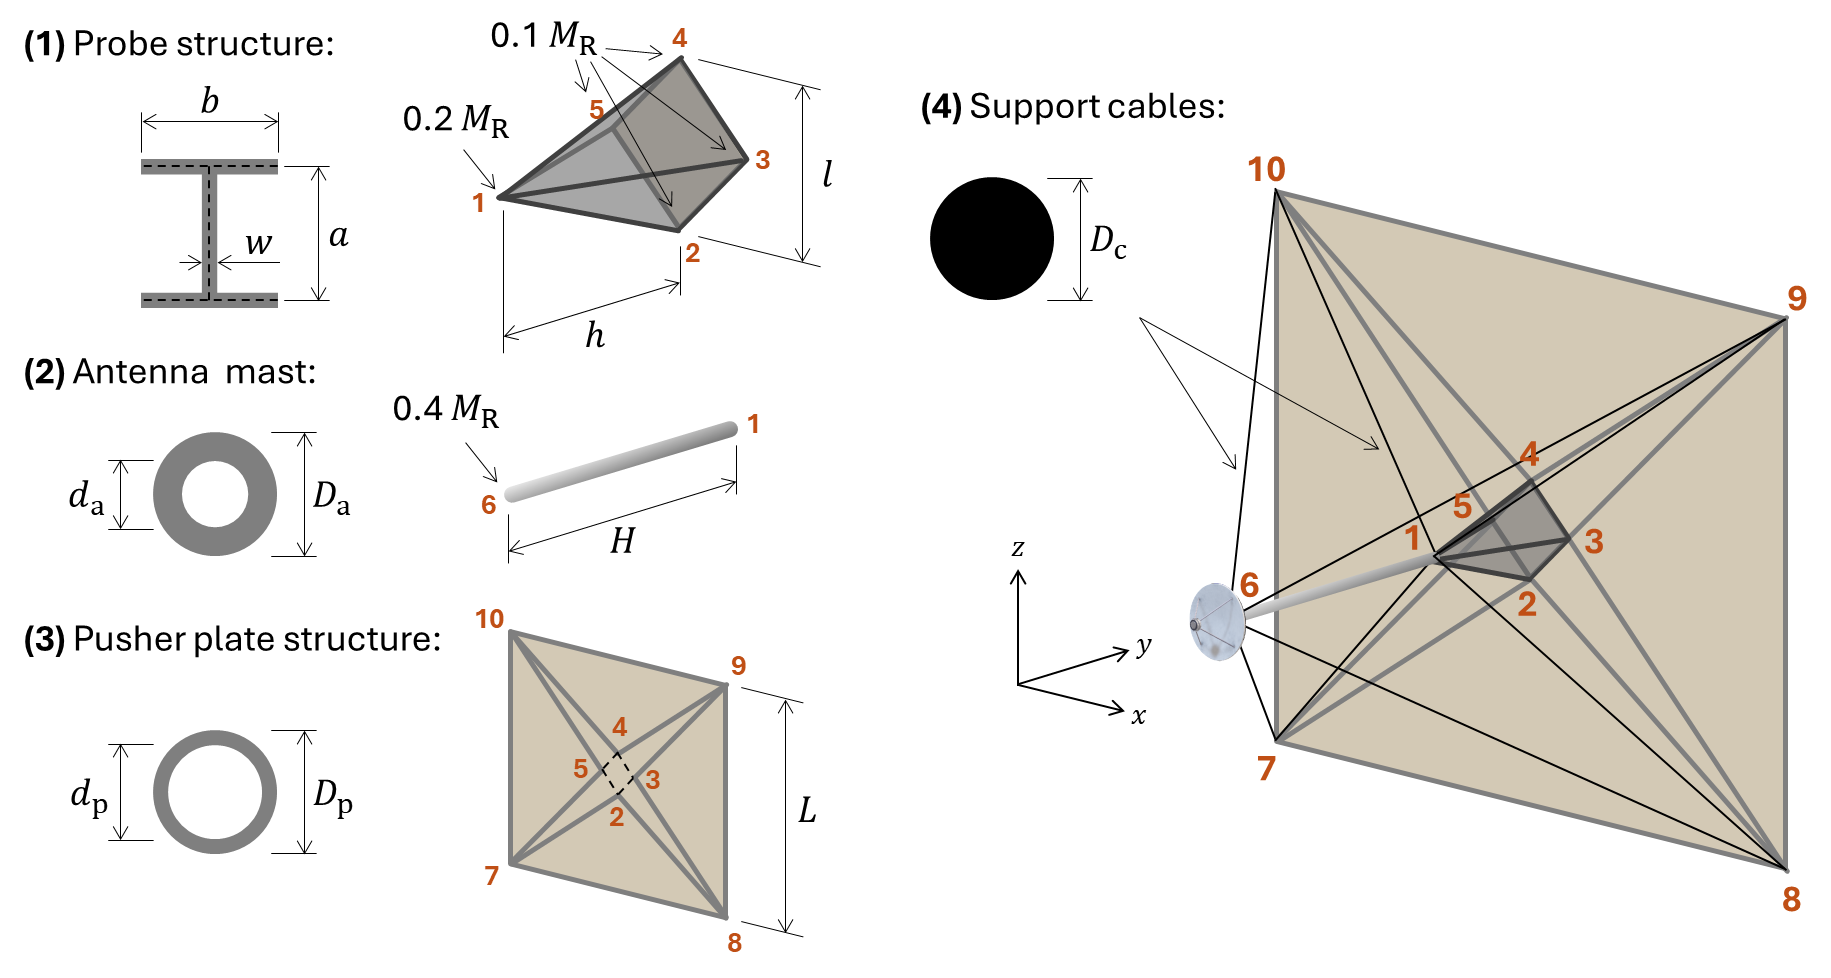

**Figure 1.** Schematic representation of the solar sail structure. Data: $L=$ 30 m, $H=$ 5 m, $l=$ 1 m, $h=$ 1 m, $a=$ 50 mm, $b=$ 25 mm, $w=$ 3 mm, $D_\text{a}=$ 75 mm, $d_\text{a}=$ 50 mm, $D_\text{p}=$ 15 mm, $d_\text{p}=$ 9 mm, $D_\text{c}=$ 5 mm.

Considering that, in each impulse, the thrust force is distributed uniformly over the the pusher plate surface (acting as a time-dependent pressure $p_\text{T}(t)$ defined previously). The following is asked:

- Plot of the deformed structure and stress-state of each element in the most critical scenario. [Optionally, get the results in a sequence of time instants of interest]

- Discuss whether the proposed design is capable of fulfilling the mission according to the hypothesis considered. Are material properties considered realistic? What changes on the solar sail structural design would you suggest to improve the chances of success of the mission? [Example: changing material or geometrical features, adding prestress to elements at risk of buckling, etc.]

Justify your arguments with quantitative metrics.

## Results

[Write here the code to produce the requested results. Comment relevant aspects of the resolution (e.g., what degrees of freedom are prescribed and why?)]

Para evaluar las tensiones y las deformaciones en la vela, hemos utilizado un solver muy similar al utilizado en la práctica 1, pero adaptandolo a 3D. En este caso, como queremos estudiar el comportamiento de toda la estructura en el espacio, no hay ningún nodo que este fijo. Sin embargo, para evitar tener un comportamiento de sólido rígido y obtener el resultado correcto, hay que fijar 6 grados de libertad (3 translaciones y 3 rotaciones). Esta es la matriz fixnod que hemos escogido:

fixnod = [ % nodo, dof, desplazamiento
    6 1 0;
    6 2 0; 
    6 3 0; 
    1 3 0; 
    1 1 0; 
    4 1 0;
    ];

Se han fijado los tres grados de libertad del nodo 6 para fijar las traslaciones y para fijar las rotaciones hemos fijado 2 grados de libertad en el nodo 1 y 1 grado de libertad en el nodo 4.

Para modelar las fuerzas inerciales y el thrust, se ha utilizado la información proporcionada en el enunciado y las siguientes fórmulas:


$$F_{i\;} =-m_i \cdot a_{i\;} =-m_{i\;} \cdot \frac{\textrm{dv}}{\textrm{dt}}$$


$F_{i\;}$es la fuerza asociada al nodo $i$; $m_{i\;}$es la masa asociada al nodo $i$ y la aceleración se calcula a partir de esta relación: $M \frac{dV}{dt} \approx \dot{m}_p(t) \frac{S}{4 \pi d^2} V_p
$


$$T_{i\;} =A_i \cdot p_t$$


$T_{i\;}$es la fuerza asociada al nodo $i$ (solo tienen thrust los nodos de la placa de empuje); $A_{i\;}$es el área efecitiva (en los nodos exteriores se utiliza $\frac{1}{\textrm{16}}S$ y en los nodos interiores $\frac{3}{16}S$) y $p_t$ se calcula como: $p_\text{T}(t) = \frac{\dot{m}_p(t)}{4 \pi d^2} V_p$ç

Como el empuje es una fuerza que varía con el tiempo, hemos modificado el solver para que realice los cálculos en diferentes instantes de tiempo. Si se quiere visualizar el resultado en función del tiempo hay que seleccionar el caso 1. Si solamente se quiere estudiar el caso más crítico, se puede seleccionar el caso 0 y así ahorrar tiempo de computación.

A continuación se muestra el código:

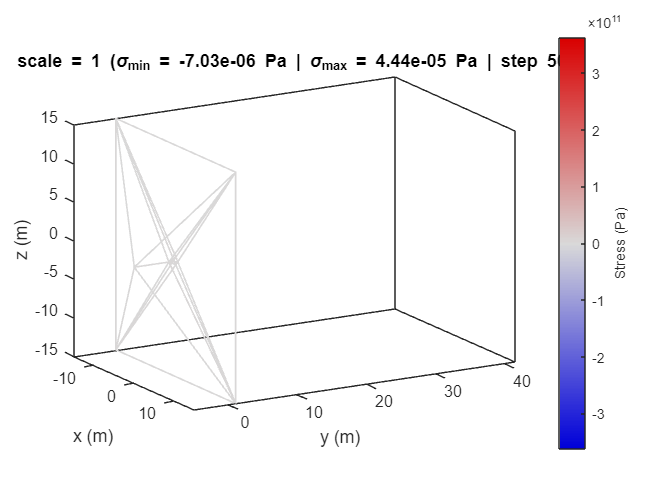


clear % Clear workspace

% Problem data
data.L = 30;       % (m)     Longitud
data.H = 5;        % (m)     Altura
data.l = 1;        % (m)     Longitud secundaria
data.h = 1;        % (m)     Altura secundaria
data.a = 0.05;     % (m)     Dimensión a
data.b = 0.025;    % (m)     Dimensión b
data.w = 0.003;    % (m)     Espesor w
data.wf = data.w;
data.Da = 0.075;   % (m)     Diámetro exterior A
data.da = 0.05;    % (m)     Diámetro interior A
data.Dp = 0.015;   % (m)     Diámetro exterior P
data.dp = 0.009;   % (m)     Diámetro interior P
data.Dc = 0.005;   % (m)     Diámetro C

% Áreas en m^2
data.A1 = 2*data.b*data.w + (data.a-data.w)*data.w;  % (m^2) Área 1
data.A2 = pi/4*(data.Da^2 - data.da^2);             % (m^2) Área 2
data.A3 = pi/4*(data.Dp^2 - data.dp^2);             % (m^2) Área 3
data.A4 = pi/4*data.Dc^2;                           % (m^2) Área 4

% Módulo de elasticidad en Pascales (Pa = N/m^2)
data.E1 = 70e9;    % (Pa) Módulo de Young 1
data.E2 = 85e9;    % (Pa) Módulo de Young 2
data.E3 = 100e9;   % (Pa) Módulo de Young 3
data.E4 = 1000e9;  % (Pa) Módulo de Young 4

% Densidades en kg/m^3
data.ro1 = 2275;   % (kg/m^3) Densidad 1
data.ro2 = 2400;   % (kg/m^3) Densidad 2
data.ro3 = 1100;   % (kg/m^3) Densidad 3
data.ro4 = 1000;   % (kg/m^3) Densidad 4

% Otros parámetros físicos
data.mp = 4.468e6;  % (kg) Masa de la detonacion 
data.tp = 0.1;      % (s)  Tiempo
data.vp = 125000e3; % (m/s) Velocidad
data.d = 200e3;  % (m)  Distancia
data.M = 100;       % (kg) Masa
data.S = 900;       % (m^2) Superficie

% Inercias (para el análisis del pandeo) 
I1 = data.w^3*(data.a-data.wf)/12 + 2*data.b^3*data.w/12;
I15 = data.w * (data.a - data.wf)^3 / 12 + 2 * (data.b * data.wf^3 / 12 + data.b * data.wf * (data.a / 2)^2);
I1 = min([I1,I15]); 
I2 = pi/64*(data.Da^4-data.da^4);
I3 = pi/64*(data.Dp^4-data.dp^4);
I4 = pi/64*data.Dc^4;
data.inercia = [I1 I2 I3 I4];

% --------------------------- Introducir datos  ------------------------------ 
% 0 = Para valor maximo 
% 1 = En funcion del tiempo 0 < t <tp
data.caso = 0;      % Caso
data.ndelta_t = 50; % Numero de instantes de tiempo que se analizaran (Para caso 1)
% ---------------------------------------------------------------------------

[disp,reac,stress,xnod,Tnod,data] = casos(data);
scale = 1; units = 'Pa';
plot3DBars(xnod,Tnod,disp,stress,scale,units)

% ANÁLISIS DEL PANDEO: para t = tp/2 (Máximas tensiones) ----------------------------------------
t = data.tp/2; 
[xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data,t);
[disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);
pandeo_analisis (data,stress,xnod,Tnod,mat,Tmat);

----------------- Análisis de Pandeo -----------------
Elemento | Material | σ (MPa)  | σ_crit (MPa) | Estado
------------------------------------------------------
       5 |        1 |  5710.32 |        37.60 | ⚠️ Falla
       6 |        1 |  5710.32 |        37.60 | ⚠️ Falla
       7 |        1 |  5710.32 |        37.60 | ⚠️ Falla
       8 |        1 |  5710.32 |        37.60 | ⚠️ Falla
       9 |        2 |  1478.43 |        17.04 | ⚠️ Falla
      10 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      11 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      12 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      13 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      14 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      15 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      16 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      17 |        3 | 14871.18 |         0.04 | ⚠️ Falla
      18 |        3 | 14761.19 |         0.02 | ⚠️ Falla
      19 |        3 | 14761.19 |     


% Búsqueda de un material que evite la ruptura:
data.caso = 0;      % Caso

D5 = 0.3; d5 = 0.275;
D6 = 0.2418; d6 = 0.2375;
D7 = 0.35; d7 = 0.3475;


Se consideran secciones cuadradas huecas para esta parte, ya que este tipo de secciones proporciona una de las mayores relaciones de inercia entre área (I/A) para una viga de dimensiones similares presentes en el enunciado (considerando el lado exterior del cuadrado es igual al diámetro exterior de la sección 2 '***Da***', y que el lado interior es igual a '***da****'*, esta sección presentaría mayor relación I/A que todos los materiales y secciones propuestas en el enunciado)

mat = [ % E, A, rho, sigma_0
    70e9,2.91e-4,2275,0;
    85e9,0.0025,2400,0;
    100e9,1.31e-4,1100,0;
    1000e9,1.9635e-4,1000,0;
    % material 5
    1000e9,D5^2-d5^2,1000,0;
    % material 6
    4000e9,D6^2-d6^2, 1000,0;
    % material 7
    6000e9,D7^2-d7^2, 1000,0;    
];
I5 = (D5^4-d5^4)/12;
I6 = (D6^4-d6^4)/12;
I7 = (D7^4-d7^4)/12;

data.inercia = [data.inercia,I5,I6,I7];

Tmat = [
    3 % 1 Probe
    3 % 2
    3 % 3
    3 % 4
    5 % 5 
    5 % 6
    5 % 7
    5 % 8
    7 % 9 Antenna mast
    6 % 10 Pusher plate structure
    6 % 11
    6 % 12
    6 % 13
    6 % 14
    6 % 15
    6 % 16
    6 % 17
    7 % 18
    7 % 19
    7 % 20
    7 % 21
    4 % 22 Support cables
    4 % 23
    4 % 24
    4 % 25
    3 % 26
    3 % 27
    3 % 28
    3 % 29
];
[disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);
long = longitud_elementos(data, xnod, Tnod);
masanod = masas_nodos(data, mat, Tmat, Tnod, long);
ms = sum(masanod)

ms = 632.8088

pandeo_analisis (data,stress,xnod,Tnod,mat,Tmat);

----------------- Análisis de Pandeo -----------------
Elemento | Material | σ (MPa)  | σ_crit (MPa) | Estado
------------------------------------------------------
       5 |        5 |   122.27 |    272442.20 | ✅ Seguro
       6 |        5 |   122.27 |    272442.20 | ✅ Seguro
       7 |        5 |   122.27 |    272442.20 | ✅ Seguro
       8 |        5 |   122.27 |    272442.20 | ✅ Seguro
       9 |        7 |  1950.44 |     48016.86 | ✅ Seguro
      10 |        6 |   863.45 |       868.28 | ✅ Seguro
      11 |        6 |   863.45 |       868.28 | ✅ Seguro
      12 |        6 |   863.45 |       868.28 | ✅ Seguro
      13 |        6 |   863.45 |       868.28 | ✅ Seguro
      14 |        6 |   863.45 |       868.28 | ✅ Seguro
      15 |        6 |   863.45 |       868.28 | ✅ Seguro
      16 |        6 |   863.45 |       868.28 | ✅ Seguro
      17 |        6 |   863.45 |       868.28 | ✅ Seguro
      18 |        7 |  1285.97 |      1333.80 | ✅ Seguro
      19 |        7 |  1285.97 |     

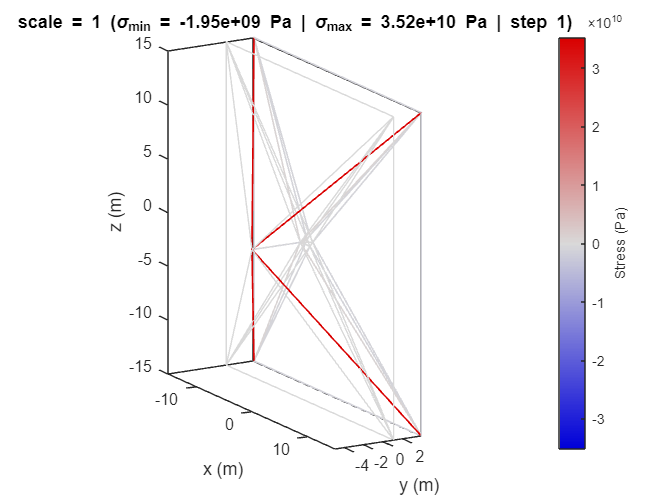

plot3DBars(xnod,Tnod,disp,stress,scale,units)

## Discussion

[Add a discussion of the results and summarize the main conclusions]

Al visualizar la estructura deformada y las tensiones en el momento más crítico, se observa que alcanzan valores del orden de 10Pa. No conocemos el límite elástico de los materiales utilizados, pero es improbable que puedan soportar tensiones tan altas. Materiales como el acero, el titanio e incluso la fibra de carbono tienen límites elásticos inferiores, por lo que sería necesario emplear materiales avanzados como el grafeno o los nanotubos de carbono. Sin embargo, estos todavía no se usan en estructuras porque son extremadamente delgados y dificiles de manipular.

En cuanto al pandeo, 21 barras fallan. Las tensiones superan ampliamente la tensión crítica de pandeo, que en la mayoría de los casos no alcanza 1 MPa, mientras que las tensiones de compresión esperadas llegan hasta 50 GPa.

Además, los materiales propuestos en el enunciado no son muy realistas. El material 4, por ejemplo, tiene un módulo de Young de 1 TPa, similar al del grafeno, que es uno de los materiales más rígidos jamás creados. No obstante, como mencionamos antes, su uso en estructuras es muy poco factible, porque es básicamente una monocapa de átomos de carbono.

Probamos diferentes estrategias para evitar el fallo por pandeo: modificar la sección para aumentar la inercia, añadir pretensión, variar la densidad... Aunque en algunas condiciones conseguimos que no fallara, la masa total de la vela superaba ampliamente los 100 kg requeridos, y las dimensiones de las secciones eran excesivas, lo que resultaba poco realista.

Por lo tanto, si no se dispone de grafeno en grandes cantidades ni de la capacidad de construir estructuras con él, además de un sistema de lanzamiento que soporte una vela más pesada, podemos concluir que este sistema no es viable.

## Code functions

Create a function to produce the *mesh* data.

function [xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data,t)

fixnod = [ % nodo, dof, desplazamiento
    6 1 0;
    6 2 0; 
    6 3 0; 
    1 3 0; 
    1 1 0; 
    4 1 0;
    ];

% Nodal coordinates
xnod = [
    0,        0,       0;
    0,        data.h, -data.l/2; 
    data.l/2, data.h,  0;
    0,        data.h,  data.l/2;
   -data.l/2, data.h,  0;
    0,       -data.H,  0;
   -data.L/2, data.h, -data.L/2; 
    data.L/2, data.h, -data.L/2;
    data.L/2, data.h,  data.L/2;
   -data.L/2, data.h,  data.L/2;
];

% Nodal connectivities
Tnod = [
    1 2
    1 3
    1 4
    1 5
    2 3
    3 4
    4 5
    5 2
    1 6
    5 7
    2 7
    2 8
    3 8
    3 9
    4 9
    4 10
    5 10
    7 8
    8 9
    9 10
    10 7
    6 7
    6 8
    6 9
    6 10
    1 7
    1 8
    1 9
    1 10
];

% Material connectivities
Tmat = [
    1 % Probe
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    2 % Antenna mast
    3 % Pusher plate structure
    3
    3
    3
    3
    3
    3
    3
    3
    3
    3
    3
    4 % Support cables
    4
    4
    4
    4
    4
    4
    4
];

% Problem dimensions
data.nnod = size(xnod,1);
data.nd = size(xnod,2);
data.ni = 3;
data.nel = size(Tnod,1);
data.nne = size(Tnod,2);
data.ndof = data.nnod*data.ni;
data.nde = data.nne*data.ni;

mat = [
    data.E1,data.A1,data.ro1,0;
    data.E2,data.A2,data.ro2,0;
    data.E3,data.A3,data.ro3,0;
    data.E4,data.A4,data.ro4,0;
];

long = longitud_elementos(data, xnod, Tnod);
masanod = masas_nodos(data, mat, Tmat, Tnod, long);
ms = sum(masanod);
mr = data.M - ms;  
masanod = masanod + mr*[0.2, 0.1, 0.1, 0.1, 0.1, 0.4, zeros(1,4)];

mp_dot = pi/2*data.mp/data.tp*sin(pi*t/data.tp);
p_dot = mp_dot*data.vp/4/pi/data.d^2;

Thrust = zeros(data.nnod,1,length(t));

for time = 1:length(t)
    Thrust(2:5,time) = 1/16*data.S*p_dot(time);   % Pressure / p_dot
    Thrust(7:10,time) = 3/16*data.S*p_dot(time);
end

acc = mp_dot/data.M*data.S*data.vp/4/pi/data.d^2;
fdata = zeros(data.nnod,3,length(t));
for time = 1:length(t)
for i = 1:data.nnod
        fdata(i,1,time) = i;
        fdata(i,2,time) = 2;
        fdata(i,3,time) = -acc*masanod(1,i) + Thrust(i,1,time);
end
end
end

Create a function to solve the structural problem.

function [disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata)

long = longitud_elementos(data, xnod, Tnod);             % Función que devuelve un vector con las longitudes
Kel = zeros(data.nde, data.nde, data.nel);              % Inicializa las matrices de rigidez elemental
fel = zeros(data.nde, data.nel);                        % Inicializa los vectores de fuerza de los elementos
R = zeros(2,data.nde,data.nel);                         % Inicializa las matrices de transformación elementales
K = zeros(data.ndof); f = zeros(data.ndof,1);           % Inicializa la matriz global y el vector de fuerzas global

Tdof = data.ni*(repelem(Tnod,1,data.ni)-1) + repmat(1:data.ni,size(Tnod)); % Matriz que guarda la información de los grados de libertad asociados a cada elemento

for i = 1:data.nel
    cx = ((xnod(Tnod(i,2),1))-(xnod(Tnod(i,1),1)))/long(i);
    cy = ((xnod(Tnod(i,2),2))-(xnod(Tnod(i,1),2)))/long(i);
    cz = ((xnod(Tnod(i,2),3))-(xnod(Tnod(i,1),3)))/long(i);

    A = [cx cy cz];
    R(:,:,i) = [A,zeros(1,3); zeros(1,3),A;];
    
    Kel(:,:,i) = (mat(Tmat(i,1),1)*mat(Tmat(i,1),2))/long(i)*R(:,:,i).'*[1, -1; -1, 1]*R(:,:,i);    
    fel(:,i) = - mat(Tmat(i,1),4) * mat(Tmat(i,1),2) * R(:,:,i).'*[-1 ; 1]; % Vector de fuerza del elemento
end


% Ensamblaje de la Matriz de rigidez global
for e = 1:data.nel
    I = Tdof(e,:);
    f(I) = f(I) + fel(:,e);
    K(I,I) = K(I,I) + Kel(:,:,e);
end

% Ensamblaje del vector de fuerzas global
for i = 1:length(fdata)
    I = data.ni * (fdata(i,1) - 1) + fdata(i,2);    
    f(I) = f(I) + fdata(i,3);
end

u = zeros(data.ndof,1); 
vr = zeros(length(fixnod), 1);
 
for i = 1:length(fixnod)
    I = data.ni*(fixnod(i,1)-1) + fixnod(i,2);
    vr(i) = I;
    u(I) = fixnod(i,3);
end

vf = setdiff(1:data.ndof,vr);
u(vf) = K(vf,vf)\(f(vf)-K(vf,vr)*u(vr));
r= K(vr,:)*u-f(vr);
disp = u;
reac = r;

uel=zeros(data.nde,1,data.nel); % Inicializa el vector de desplazamientos global para cada elemento
uel_prima = zeros(data.nne,1,data.nel); % Inicializa el vector de desplazamientos local para cada elemento
strain = zeros(data.nel,1); % Inicializa el vector de deformaciones
stress = zeros(data.nel,1); % Inicializa el vector de tensiones


for e = 1:data.nel
    I = Tdof(e,:);
    uel(:,1,e) = u(I);
    uel_prima(:,:,e) = R(:,:,e)*uel(:,:,e);
    strain(e,1) = (uel_prima(2,1,e)-uel_prima(1,1,e))/long(e);
    stress(e,1) = strain(e,1)*mat(Tmat(e),1)+mat(Tmat(e),4);
end
end

*mat = [E, A, ro, sigma_0]*

*3) Cálculo de las longitudes de los elementos  *

function [long] = longitud_elementos(data, xnod, Tnod)
for i= 1:data.nel
    long(i)=sqrt(((xnod(Tnod(i,2),1))-(xnod(Tnod(i,1),1)))^2+((xnod(Tnod(i,2),2))-(xnod(Tnod(i,1),2)))^2+((xnod(Tnod(i,2),3))-(xnod(Tnod(i,1),3)))^2);
end
end

*4) Cálculo de masas de los nodos *

function [masanod] = masas_nodos(data, mat, Tmat, Tnod, long)
masael = zeros(1,data.nel);     % Inicializa una matriz con las masas de cada elemento
masanod = zeros(1,data.nnod);   % Inicializa una matriz con las masas de cada nodo
for i=1:data.nel
    masael(1,i) = mat(Tmat(i),2)*mat(Tmat(i),3)*long(i);
    for j =1:2
        masanod(Tnod(i,j)) = masanod(Tnod(i,j)) + masael(i)/2; % Suma la mitad de la masa de un elemento en cada uno de los nodos que lo forman
    end
end
end


*5) Analizar pandeo *

function pandeo_analisis(data, stress, xnod, Tnod, mat, Tmat)
    long = longitud_elementos(data, xnod, Tnod); % Cálculo de longitudes
    fallos = 0;  % Contador de elementos que fallan
    elementos_no_fallan = 0; % Contador de elementos que no fallan
    data.pandeo = 0;  % Inicialización de pandeo en la estructura

    fprintf('----------------- Análisis de Pandeo -----------------\n');
    fprintf('Elemento | Material | σ (MPa)  | σ_crit (MPa) | Estado\n');
    fprintf('------------------------------------------------------\n');

    % Recorremos todos los elementos
    for i = 1:data.nel
        if stress(i) < 0  % Solo analizamos elementos con compresión
            elemento_critico = i;
            sigma = abs(stress(i)) / 1e6; % Conversión a MPa

            % Propiedades del material del elemento
            E = mat(Tmat(elemento_critico), 1);  % Módulo de elasticidad
            I = data.inercia(Tmat(elemento_critico));  % Momento de inercia
            A = mat(Tmat(elemento_critico), 2);  % Área de la sección transversal

            % Cálculo de la tensión crítica de pandeo (Euler) en MPa
            sigma_crit = (pi^2 * E * I) / (long(elemento_critico)^2 * A) / 1e6;

            % Determinar si el elemento falla o no
            if sigma_crit <= sigma
                estado = '⚠️ Falla';
                fallos = fallos + 1;
            else
                estado = '✅ Seguro';
                elementos_no_fallan = elementos_no_fallan + 1;
            end

            % Mostrar información del elemento en una sola línea
            fprintf('%8.0f | %8.0f | %8.2f | %12.2f | %s\n', ...
                    elemento_critico, Tmat(elemento_critico), sigma, sigma_crit, estado);
        end
    end

    % Resultados finales
    fprintf('------------------------------------------------------\n');
    if elementos_no_fallan == data.nel
        fprintf('✅ La estructura NO se romperá por pandeo.\n');
    else
        fprintf('⚠️  Número total de barras que fallan por pandeo: %.0f\n', fallos);
    end

end


*6) Seleccionar caso *

function [DISP,REAC,STRESS,xnod,Tnod,data] = casos(data)

if data.caso == 1

time = linspace(0,data.tp,data.ndelta_t); 

for i = 1:length(time)
    t = time(i);
    [xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data,t);
    [disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);
    DISP(:,i) = disp;
    REAC(:,i) = reac;
    STRESS(:,i) = stress;
end
elseif data.caso == 0
    t = data.tp/2;
    [xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data,t);
    [disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);
    DISP = disp;
    REAC = reac;
    STRESS = stress;
else 
    error('Seleccionar caso valido')
end
end 



Use the following function to plot the deformed structure. Pay attention to the inputs:

- `disp` is a column vector or a matrix in which each column contains all degrees of freedom (displacements) corresponding to a timestep.

- `stress` is a column vector or a  matrix in which each column contains the stress of each element corresponding to a timestep.

- `scale` is a scaling factor to amplify the displayed deformed (e.g., setting `scale=100` will show the structure 100 times more deformed that the actual deformation values).

- `units` can be used to specify the units in which the stresses are given (e.g., set `units='Pa'` is the values in stress are given in Pa, or `units='MPa'` if they are given in MPa).

Note: If `disp` and `stress` are matrices, the function will produce an animation showing how the structure deforms at each timestep.

function plot3DBars(xnod,Tnod,disp,stress,scale,units)

% Number of steps
N = size(disp,2);

% Precomputations
X = xnod(:,1);
Y = xnod(:,2);
Z = xnod(:,3);
Ux = scale*disp(1:3:end,1);
Uy = scale*disp(2:3:end,1);
Uz = scale*disp(3:3:end,1);
smin = min(stress(:));
smax = max(stress(:));
xmax = max([max(X),max(X+scale*disp(1:3:end,:),[],'all')]);
xmin = min([min(X),min(X+scale*disp(1:3:end,:),[],'all')]);
ymax = max([max(Y),max(Y+scale*disp(2:3:end,:),[],'all')]);
ymin = min([min(Y),min(Y+scale*disp(2:3:end,:),[],'all')]);
zmax = max([max(Z),max(Z+scale*disp(3:3:end,:),[],'all')]);
zmin = min([min(Z),min(Z+scale*disp(3:3:end,:),[],'all')]);

% Open plot window
figure; box on; hold on; axis equal; view(60,15);

% Plot undeformed structure
plot3(X(Tnod'),Y(Tnod'),Z(Tnod'),'-', ...
   'Color',0.85*[1,1,1],'LineWidth',0.5);

% Plot deformed structure with colorbar for stresses 
p = patch(X(Tnod')+Ux(Tnod'),Y(Tnod')+Uy(Tnod'),Z(Tnod')+Uz(Tnod'),[stress(:,1)';stress(:,1)'], ...
    'EdgeColor','interp','LineWidth',1);

% Limits
xlim([xmin,xmax])
ylim([ymin,ymax])
zlim([zmin,zmax])

% Colorbar settings
%clims = get(gca,'clim');
clim(max(abs([smin,smax,1]))*[-1,1]);
n = 128; % Number of rows
c1 = 2/3; % Blue
c2 = 0; % Red
s = 0.85; % Saturation
c = hsv2rgb([c1*ones(1,n),c2*ones(1,n);1:-1/(n-1):0,1/n:1/n:1;s*ones(1,2*n)]');
colormap(c); 
cb = colorbar;

% Add labels
title(sprintf('scale = %g (\\sigma_{min} = %.3g %s | \\sigma_{max} = %.3g %s | step %i)',scale,min(stress(:,1)),units,max(stress(:,1)),units,1)); 
xlabel('x (m)'); 
ylabel('y (m)');
zlabel('z (m)');
cb.Label.String = sprintf('Stress (%s)',units); 

% Plot different timesteps
for i = 1:N
    Ux = scale*disp(1:3:end,i);
    Uy = scale*disp(2:3:end,i);
    Uz = scale*disp(3:3:end,i);
    p.XData = X(Tnod')+Ux(Tnod');
    p.YData = Y(Tnod')+Uy(Tnod');
    p.ZData = Z(Tnod')+Uz(Tnod');
    p.CData = [stress(:,i)';stress(:,i)'];
    title(sprintf('scale = %g (\\sigma_{min} = %.3g %s | \\sigma_{max} = %.3g %s | step %i)',scale,min(stress(:,i)),units,max(stress(:,i)),units,i));
    drawnow
end

end